clear cd;
cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\')
file = 'A09E.mat';
load(file);
cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf\true_labels')
load(file);
pos_nan = find(isnan(s));
s(pos_nan) = 0;
cd('C:\Users\User\Downloads\Compressed\BCICIV_2a_gdf')
eeg = struct();
eeg.fs = h.SampleRate;
LH_po = h.TRIG(find(classlabel == 1));
RH_po = h.TRIG(find(classlabel == 2)); 
FE_po = h.TRIG(find(classlabel == 3));
TO_po = h.TRIG(find(classlabel == 4));

%Left hand
for i=1:length(LH_po)
    eeg.data.lh(i,:,:) = [s((LH_po(i)+2*eeg.fs:LH_po(i)+4.999*eeg.fs), :)];
end


for i=1:72
    x_value = eeg.data.lh(i,:,:);
    eeg.fil_data.lh(i,:,:) = bp_filter(2, 8, 30, eeg.fs, x_value);
end

%Right hand
for i=1:length(RH_po)
    eeg.data.rh(i,:,:) = [s((RH_po(i)+2*eeg.fs:RH_po(i)+4.999*eeg.fs), :)];
end


for i=1:72
    x_value = eeg.data.rh(i,:,:);
    eeg.fil_data.rh(i,:,:) = bp_filter(5, 8, 30, eeg.fs, x_value);
end


%foot
for i=1:length(FE_po)
    eeg.data.fe(i,:,:) = [s((FE_po(i)+2*eeg.fs:FE_po(i)+4.999*eeg.fs), :)];
end
for i=1:72
    x_value = eeg.data.fe(i,:,:);
    eeg.fil_data.fe(i,:,:) = bp_filter(5, 8, 30, eeg.fs, x_value);
end

%Tongue
for i=1:length(TO_po)
    eeg.data.to(i,:,:) = [s((TO_po(i)+2*eeg.fs:TO_po(i)+4.999*eeg.fs), :)];
end
for i=1:72
    x_value = eeg.data.to(i,:,:);
    eeg.fil_data.to(i,:,:) = bp_filter(5, 8, 30, eeg.fs, x_value);
end


eeg.time = (0:length(eeg.data.lh)-1);
cd('C:\Users\User\Desktop\4-th year project\test')

channel = {};
for i=1:22
    channel = [channel, sprintf('channel_%d', i)];
end
data = struct();
data.time = eeg.time/eeg.fs;
wname = 'db4';
det = ['d3', 'd4'];
x = 0;
for tr=1+x:72+x
    clear data;
    for num_ch=1:22
        signal = eeg.data.lh(tr-x,:,num_ch);
        [c,l] = wavedec(signal,4,wname);
        cd = detcoef(c,l, "dcells");
        data.(channel{num_ch}).d4 = cd{4};
        data.(channel{num_ch}).d3 = cd{3};
    end
    
    x_plot = [];
    
    for ch = 1:22
        log_data = [data.(channel{ch}).d4];
        x_plot = [x_plot; log_data];
    end
    lh(tr, :, :) = x_plot;
end

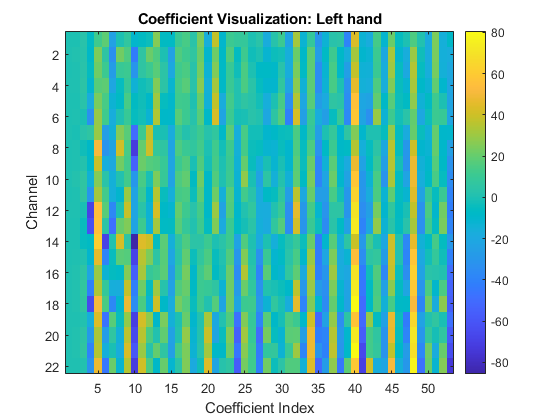

x_p = squeeze(lh(3,:,:));
imagesc(x_p)
title("Coefficient Visualization: Left hand")
xlabel('Coefficient Index')
ylabel('Channel')
colorbar();

% 